# The Rössler equations

The purpose of this demonstration is to show you how to produce all the figures in Strogatz's discussion of the Rössler system in Section 10.6 of the book. This uses material that I discussed in the earlier tutorials on **function handles** and **ode45.**  It also makes use of a new concept in MATLAB's ODE solver, the **events location** feature, which will allow us to compute Poincaré sections.

The Rossler equations (Strogatz p 383) depend on three parameters **a, b, c.** 


$$\dot{x} = -y-z\\
\dot{y} = x + ay \\
\dot{z} = b+z(x-c)$$


The function **ode45** requires that the function only take the two inputs **t** and **y**. The best way to pass the parameters is to use a MATLAB programming construct called **anonymous functions**, which is described in a separate document. The following example shows how to do this.

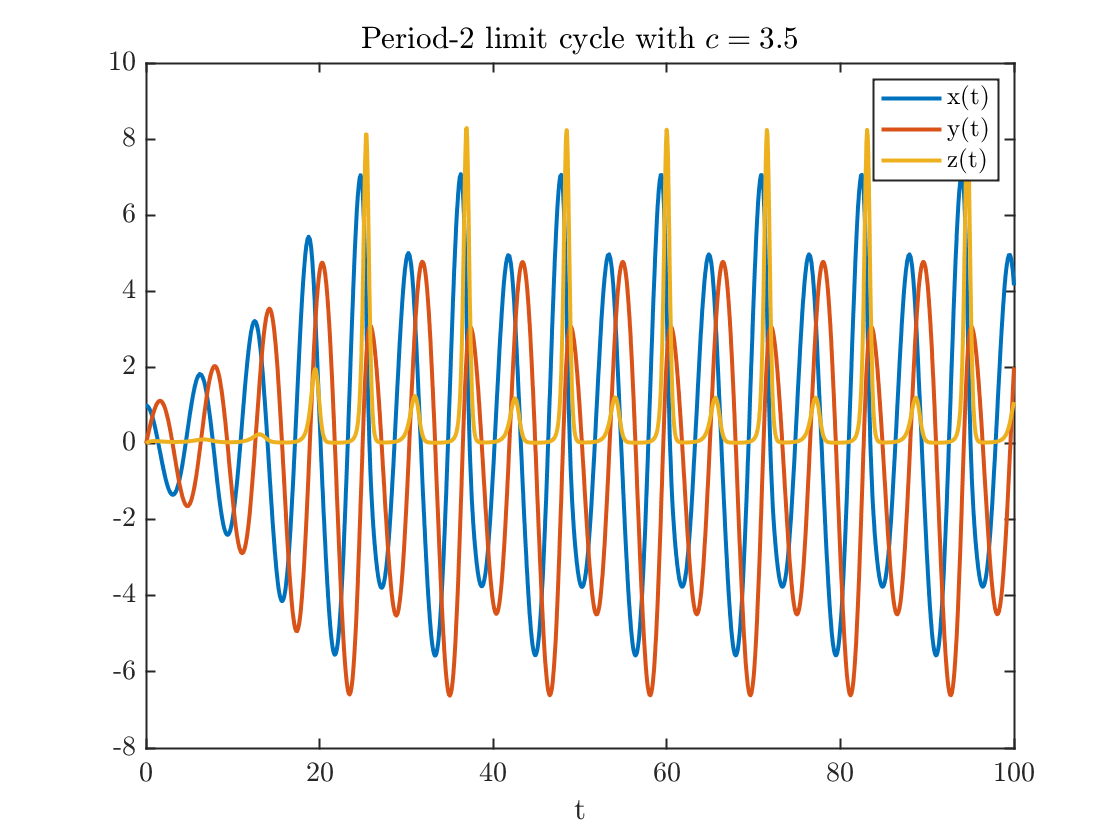

a=0.2; b=0.2; c=3.5;
myODE=@(t,y)rossler(t,y,a,b,c);
tspan=[0 100]; % Time span
y0=[1 0 0];
[t,y]=ode45(myODE,tspan,y0);
plot(t,y);legend('x(t)','y(t)','z(t)');xlabel('t')
title('Period-2 limit cycle with $c=3.5$')

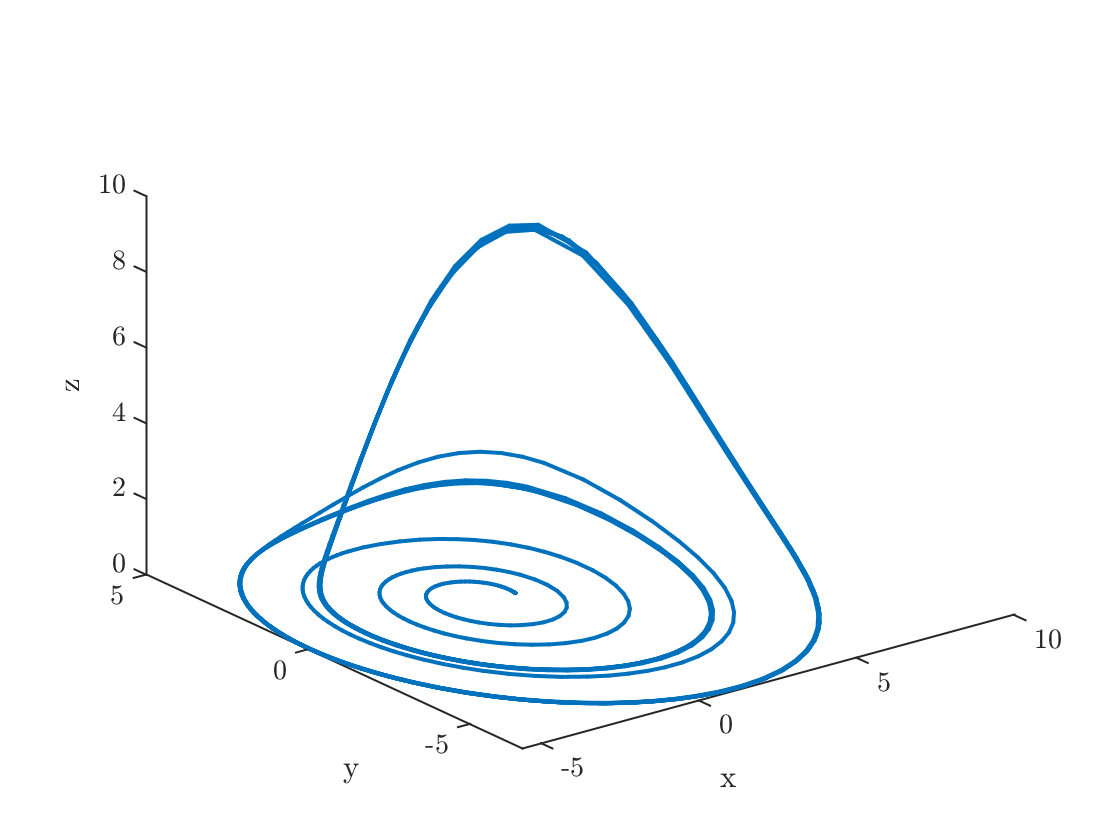

figure
plot3(y(:,1),y(:,2),y(:,3))
xlabel('x');ylabel('y');zlabel('z')

The command `myODE=@(t,y)rossler(t,y,a,b,c)` defines a function handle to a function `myODE` that depends only on the two variables `t` and `y`**. **Note that since `myODE` is already a function handle, it does not need an `@` sign.

## Four representative solutions

Reproducing Figure 10.6.6

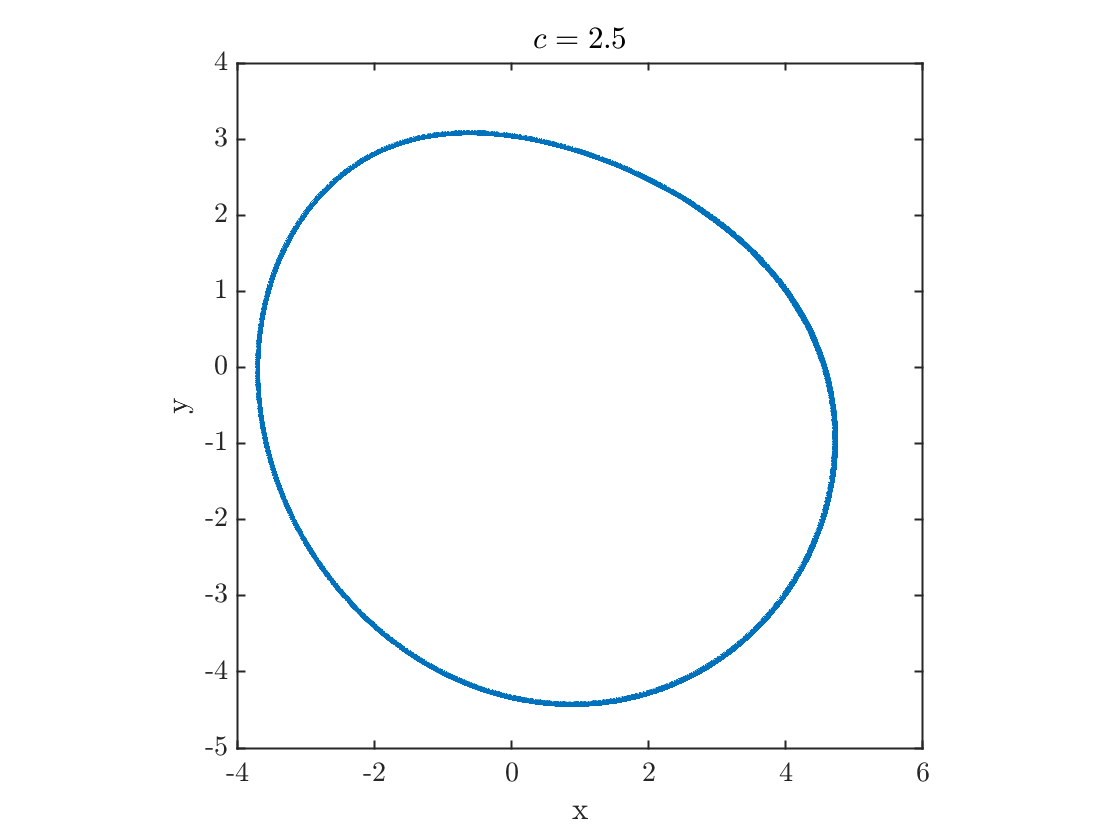

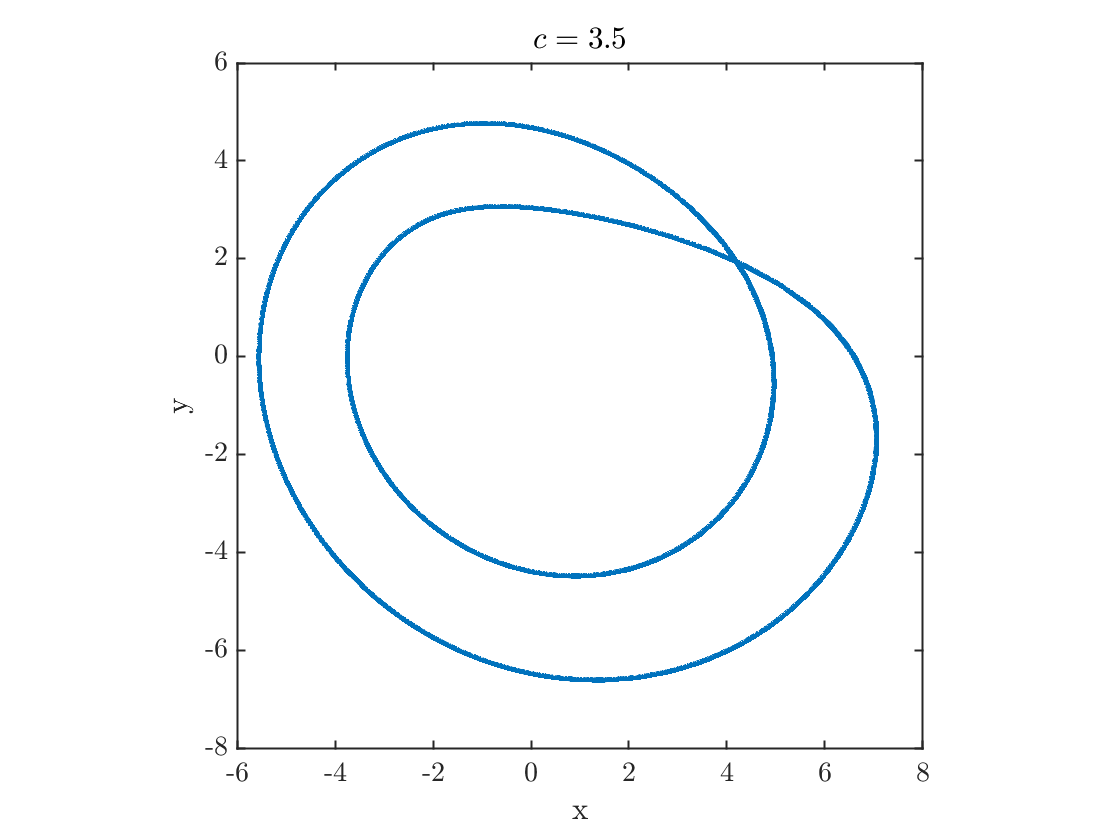

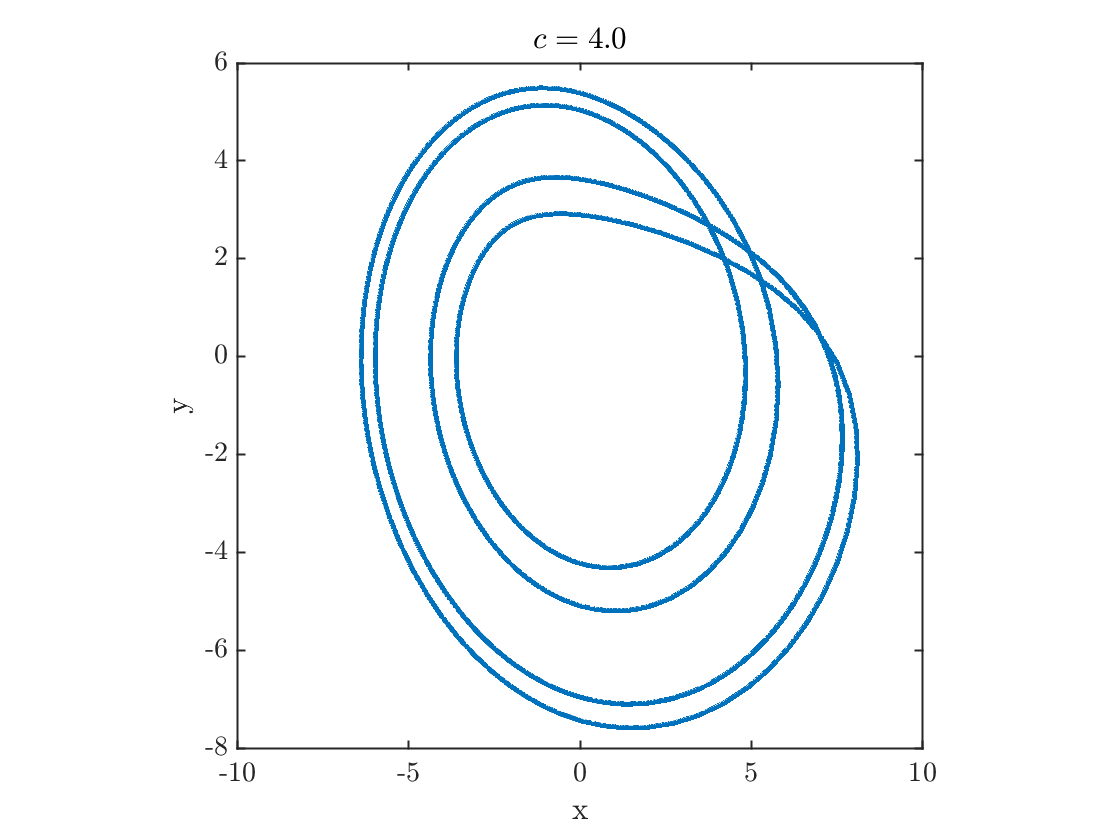

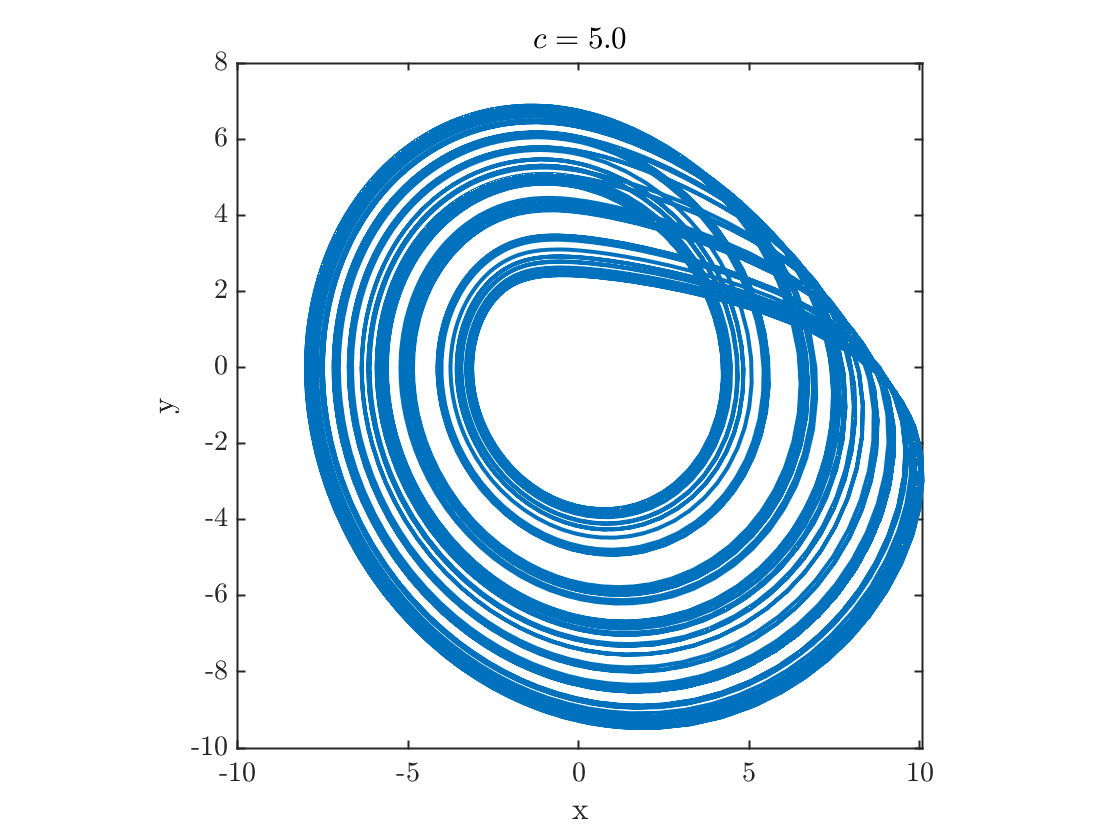

cVector=[2.5 3.5 4 5];
for k=1:4
    c=cVector(k);
    myODE=@(t,y)rossler(t,y,a,b,c);
    tspan=[0 600]; % Time span
    tTransient=200;
    y0=[1 0 0];
    [t,y]=ode45(myODE,tspan,y0);
    spot=find(t>tTransient,1,'first');
    y=y(spot:end,:);
    figure
    plot(y(:,1),y(:,2))
    axis equal square
    xlabel('x');ylabel('y');
    title(sprintf('$c=%0.1f$',c))    
end

## Computing Poincare Sections and Other Discrete Visualizations

A standard visualization is to plot the solution at a discrete series of times $t_n$where some event occurs. In a Poincaré section, we usually choose that $x_j(t_n) = 0$ and $\dot{x}_j(t_n)>0$ (to ensure that the solution passes through the surface of section in the same direction each time). Figure 10.6.7 on p. 385 shows a slightly different section. The times $t_n$ represent the successive maxima. Therefore we want to find times $t_n$ for which $\dot{x} = -y - z =0$ (critical point condition) and $\ddot{x}<0$.

MATLAB's ode solvers have an *event-finding* feature that allows us to locate the times at which events occur. Complete documentation can be found in the documentation or at [this link](https://www.mathworks.com/help/matlab/math/ode-event-location.html). First, we need to create an *events* function, given below in the external functions section of this live script.

This function must return three vectors, each of the same length:

- **value: **each element of this vector is a function value whose zero defines an event

- **isterminal: **1 if the associated event is terminal, that is, if the ode solver should quit when the event is located, 0 otherwise

- **direction: **describes the direction of the zero, that is whether the zero occurs while the function is increasing (direction=1), decreasing (direction=-1), or if either direction counts (direction=0)

Here is an example where we call the events finder

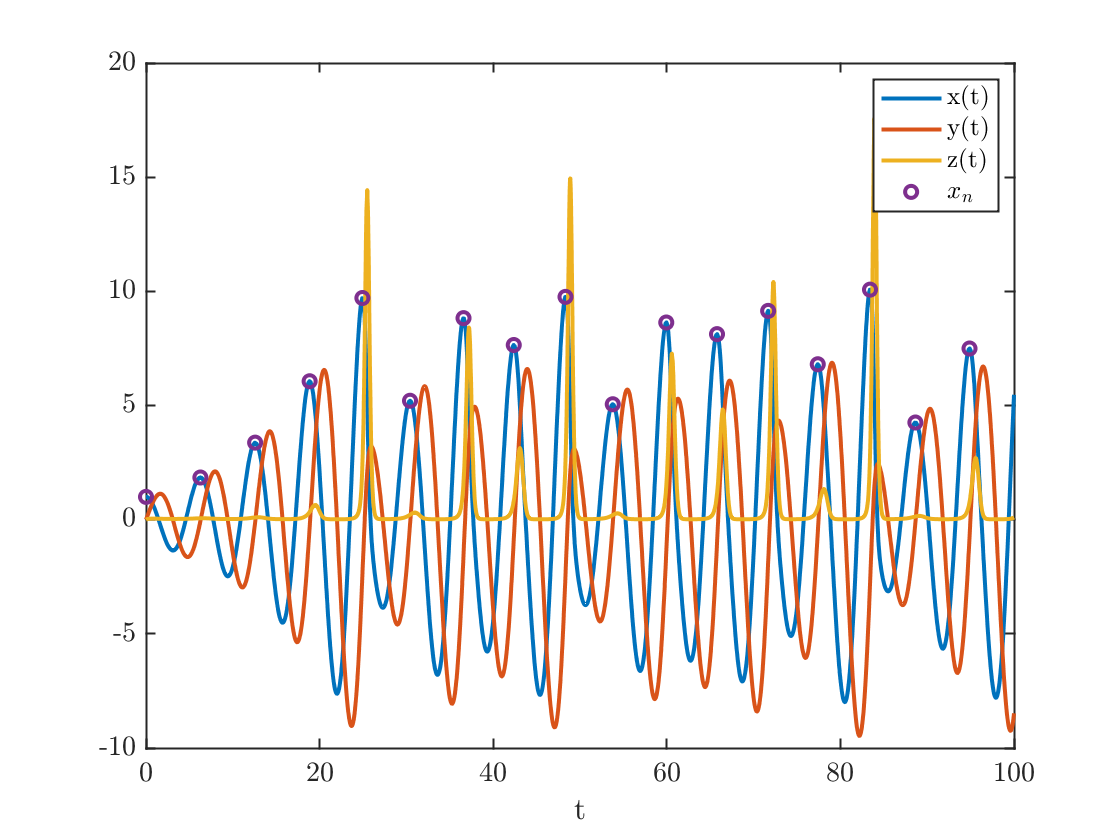

a=0.2; b=0.2; c=5;
myODE=@(t,y)rossler(t,y,a,b,c);
tspan=[0 100]; % Time span
y0=[1 0 0];
options=odeset('events',@rosslerXMaxEvent);
[t,y,te,ye,ie]=ode45(myODE,tspan,y0,options);
plot(t,y,te,ye(:,1),'o');
legend('x(t)','y(t)','z(t)','$x_n$');xlabel('t')

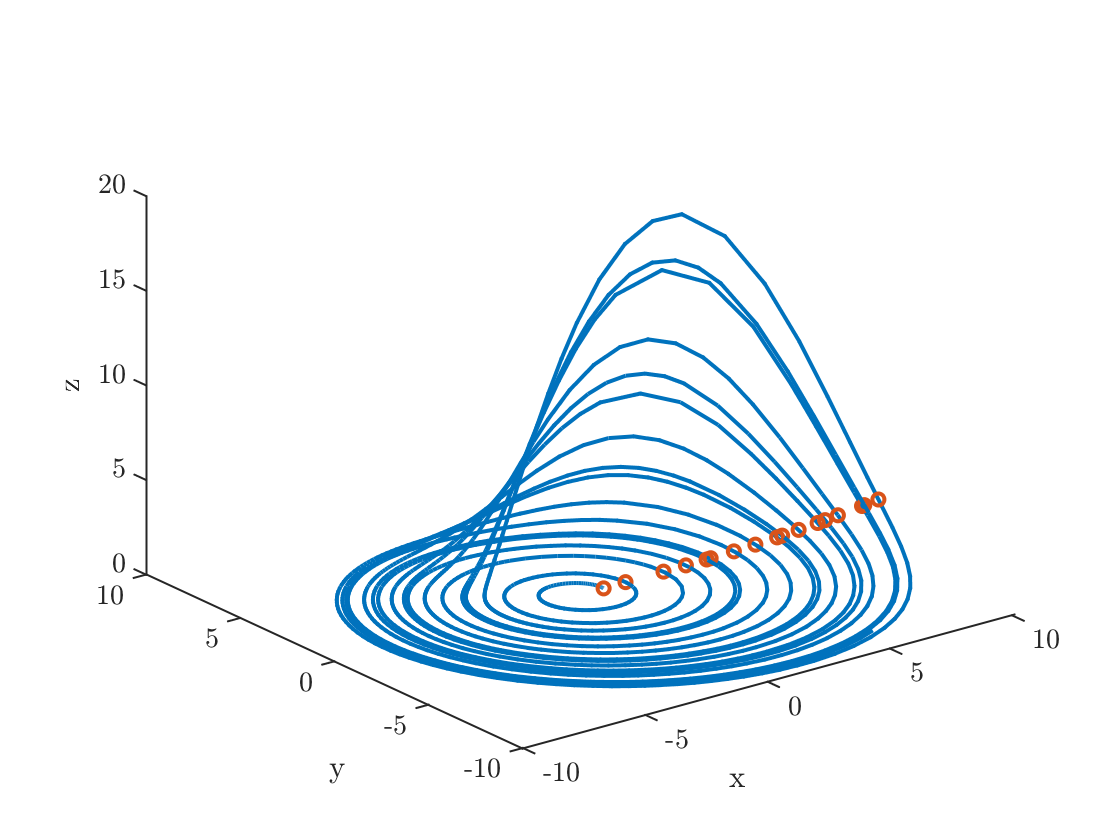

figure
plot3(y(:,1),y(:,2),y(:,3),ye(:,1),ye(:,2),ye(:,3),'o')
xlabel('x');ylabel('y');zlabel('z')

Notice that there's a fifth output called `ie`. This labels the type of event found. This is useful if you want to track multiple types of events in the same run. 

You can see that using the event locator required we modify the call to **ode45** by adding the fourth input, a variable called **options**. We set **options **on the line before using the **odeset **command. This allows us to set some options for the ODE solver. For our purposes, just copy the syntax I've used and note that I used a function handle to reference my m-file.

Note that when we use the event locator, **ode45** returns three additional output variables:

- **te:** a vector containing the times at which the events occur

- **ye: **an array containing the function values at those times

- **ie: **a vector containing labels of the events located. Since we only defined one type of events, every element of our **ie** is identically 1. 

**MATLAB Hint: **Since we don't use the variable `ie` and it is the final output argument, we can just leave it out. We could also replace it in the output argument list with a tilde (the  '`~`' sign), which we do below.

## The maximum-to-maximum map

Here is a longer run reproducing figure 10.6.7:

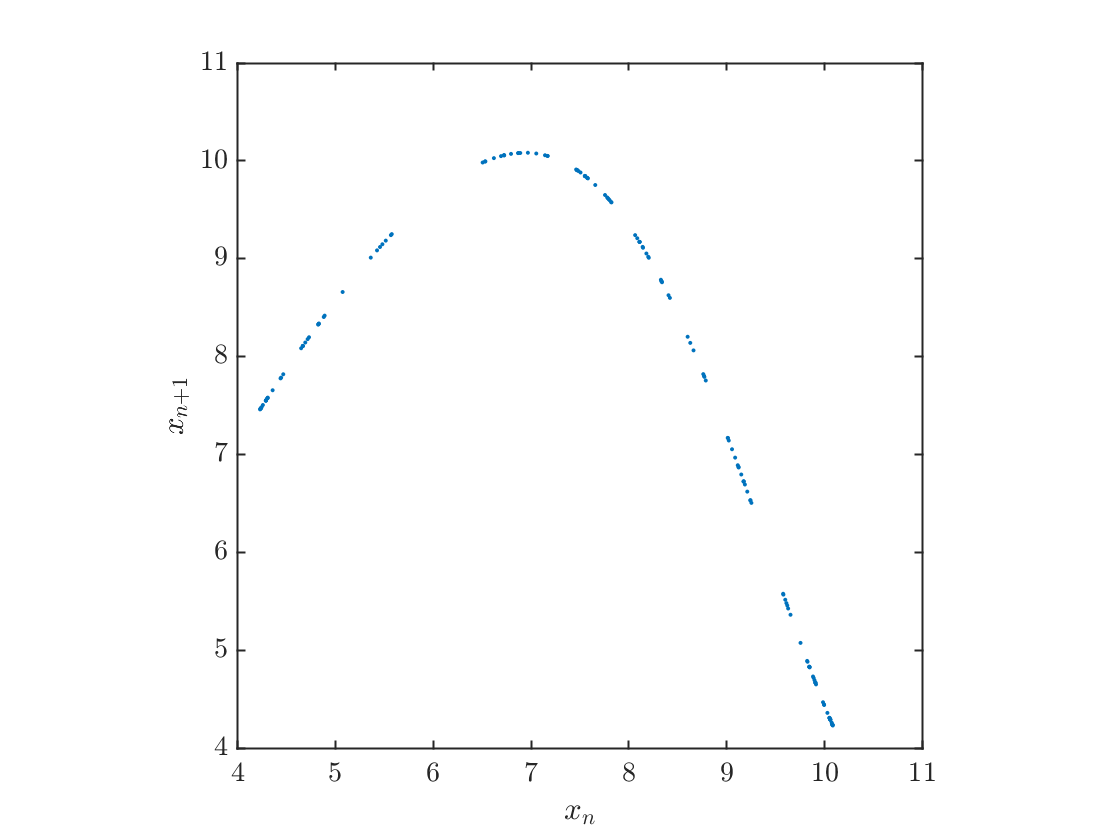

tspan=[0 1000]; % Time span
tTransient=100; % Transient time
[t,y,te,ye,~]=ode45(myODE,tspan,y0,options);
ye=ye(te>tTransient,:); % Throw away an initial transient
figure
plot(ye(1:end-1,1),ye(2:end,1),'.');
axis equal square
xlabel('$x_n$');ylabel('$x_{n+1}$');

## Orbit diagram

Now we reproduce figure 10.6.8

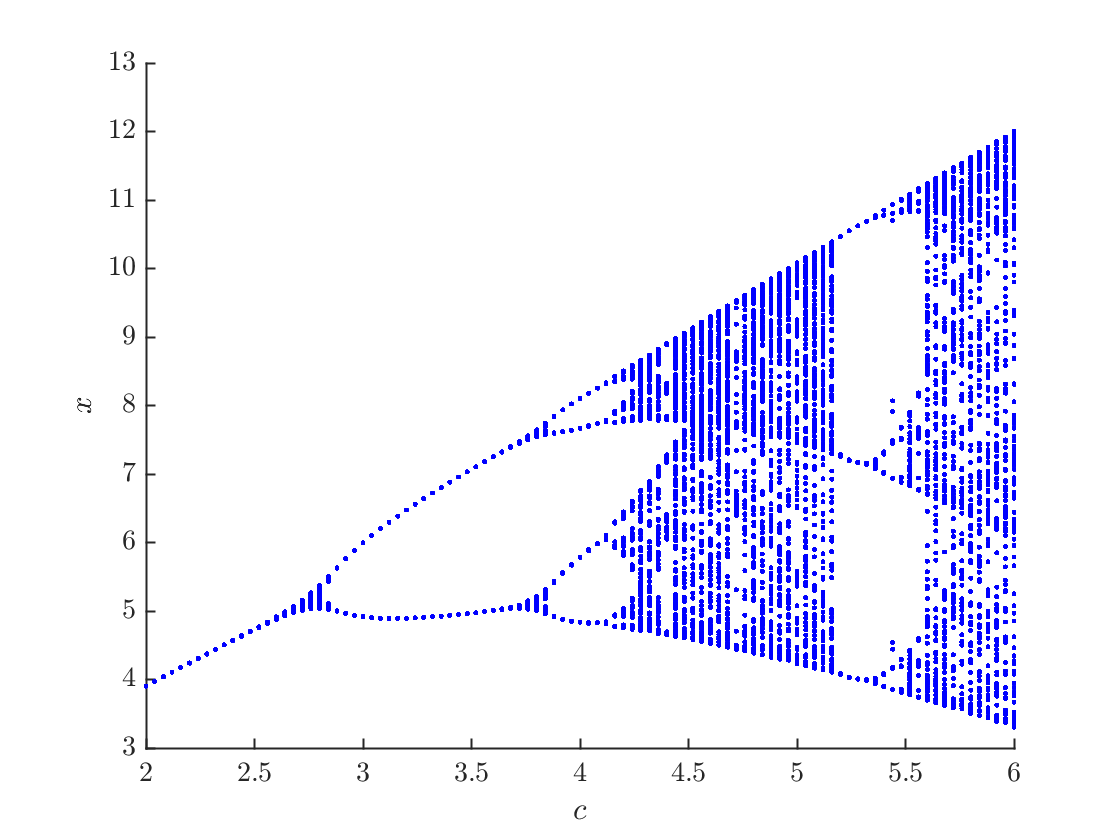

nC=101;cMin=2;cMax=6;
cVec=linspace(cMin,cMax,nC);
clf;hold on
for k=1:nC
    c=cVec(k);
    myODE=@(t,y)rossler(t,y,a,b,c);
    [t,y,te,ye]=ode45(myODE,tspan,y0,options);
    ye=ye(te>tTransient,:);
    plot(c*ones(length(ye)),ye(:,1),'b.')
end
xlabel('$c$');ylabel('$x$')

## Functions called

The Rössler ODE system

function dydt= rossler(t,y,a,b,c)
dydt=zeros(3,1);
dydt(1) = -y(2) - y(3);
dydt(2) = y(1) + a*y(2);
dydt(3) = b + y(3)*(y(1)-c);
end

The **events** program that sets $\dot{x}=0$

function [value, isterminal,direction]=rosslerXMaxEvent(t,y)
value=-y(2)-y(3); % This sets dx/dt=0
isterminal=0;    % If isterminal=1, then the simulation quits when the event occurs
direction = -1;  % because we want the event to cross zero in a decreasing direction
end